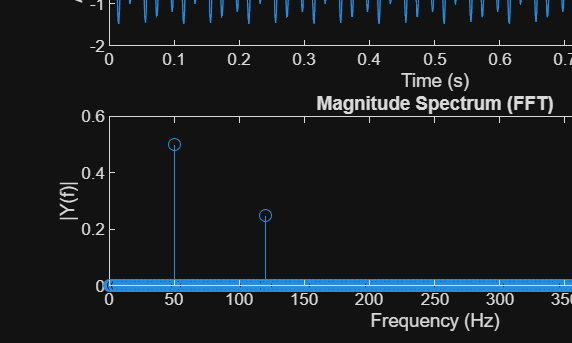

% --- Parameters ---
fs = 1000;                 % Sampling frequency (Hz)
t = 0:1/fs:1-1/fs;         % 1 second of samples

% --- Example signal ---
f1 = 50;                   % Frequency component 1 (Hz)
f2 = 120;                  % Frequency component 2 (Hz)
signal = sin(2*pi*f1*t) + 0.5*sin(2*pi*f2*t);

% --- Compute FFT ---
N = length(signal);        % Number of samples
Y = fft(signal);           % Compute FFT
f = (0:N-1)*(fs/N);        % Frequency vector (Hz)

% --- Magnitude spectrum ---
magnitude = abs(Y)/N;      % Normalize magnitude

% Only plot first half of spectrum (positive frequencies)
half_N = floor(N/2);
f_half = f(1:half_N);
mag_half = magnitude(1:half_N);

% --- Plot signal ---
figure;
subplot(2,1,1)
plot(t, signal)
title('Time-domain signal')
xlabel('Time (s)')
ylabel('Amplitude')

% --- Plot FFT magnitude ---
subplot(2,1,2)
stem(f_half, mag_half)
title('Magnitude Spectrum (FFT)')
xlabel('Frequency (Hz)')
ylabel('|Y(f)|')
xlim([0 fs/2])